# Horizontal Wave Number Spectrum

### Define parameters: latitude, stratification, local depth

%Stratification
N0 = 3*2*pi/3600;
L_gm = 1300;
N2Func = @(z) N0*N0*exp(2*z/L_gm);
latitude=33;

%Depth
Lz=4000;       


### Initialize the function

im = InternalGravityWaveSpectrum(N2Func,Lz,nModes=128);

### Initializing Wave-Vortex Model for comparisons

One VERY important thing is to run the model and the toolbox in similar scales.

**Horizontal:** I asked the toolbox to create waves with the horizontal scales between

100km and 1km. At same time I run the WVM with a 200km domain and a 782 m dx.

**Vertical: **I run the toolbox and the model with the same depth and same number of vertical mode. 

%%%% DOMAIN
N = 64 %256;
aspectRatio = 1;

Lx = 200e3;
Ly = aspectRatio*200e3;

Nx = N;
Ny = aspectRatio*N;
Nz = 128+1; % 2^n + 1 grid points, to match the Winters model, but 2^n ok too.

wvt = WVTransformBoussinesq([Lx, Ly, Lz], [Nx, Ny, Nz], latitude=latitude, N2=N2Func);
wvt.initWithAlternativeSpectrum;

### Get the complex velocity from WVModel in function of K-band and vertical mode, j.

%FMatrix and GMatrix are hydrostatic [Nj,Nz]
% Ap Am [Nj,Nkl]
u_klz = wvt.PF0inv*(wvt.P0 .*(wvt.UAp .* wvt.Ap + wvt.UAm .* wvt.Am));

u_Kz=zeros(wvt.Nj,length(wvt.kRadial));

kRadial = wvt.kRadial;
Kh = wvt.Kh(1,:);
dk = kRadial(2)-kRadial(1);

for iK=1:length(kRadial)
    for indz=1:length(wvt.z)
        indicesForK = kRadial(iK)-dk/2 < Kh & Kh <= kRadial(iK)+dk/2;
        u_Kz(indz,iK)= sum(u_klz(indz,indicesForK));
    end
end


Interping for a specific depth

z=-300;
wvtHKE =((1/2)*(abs(u_Kz)).^2);
wvtHKEatZ=interp1(wvt.z,wvtHKE,z); 


## Plotting

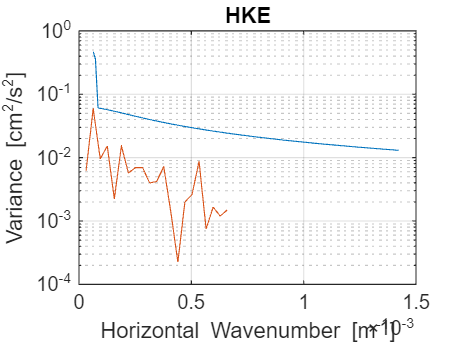

clf
HKEAtHorizontalWavenumber = im.energyAtHorizontalWavenumber(z,'HKE',mask=1);
hold on
semilogy(wvt.kRadial,wvtHKEatZ*1000)